clc
close all
clear all

# In Class Group Excersize

Roshan Jaiswal-Ferri, Stefan Rosu, Jack Schafer, Jordan Powell

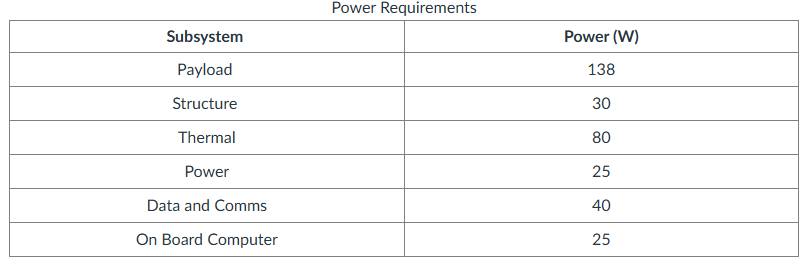

- Plot Eclipse Time vs Orbital Altitude. (5 pts)

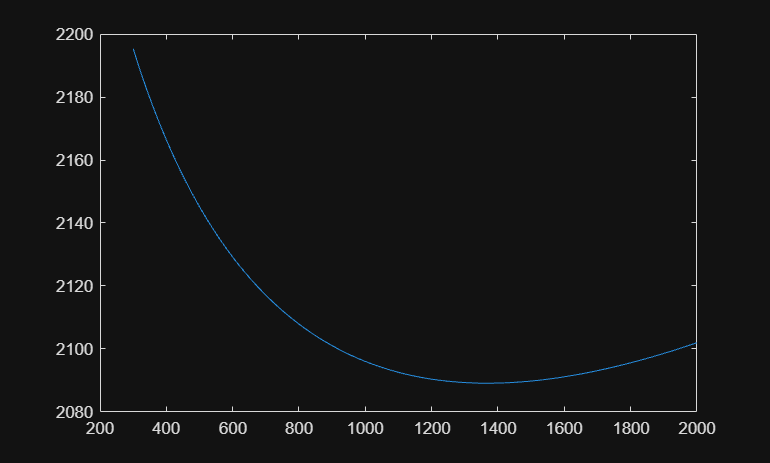

Re = 6378;
mu = 398600;
alt = 300:20:2000;
Rsc = Re + alt;

beta = 0; % Assumed
P = 2*pi*sqrt(Rsc.^3/mu);
fe = (1/pi) * asin( sqrt((Re./Rsc).^2 - sin(beta)^2) / cos(beta) );

tEclipse = P.*fe;
figure()
plot(alt, tEclipse)

- Plot Daylight Time vs Orbital Altitude. (5 pts)

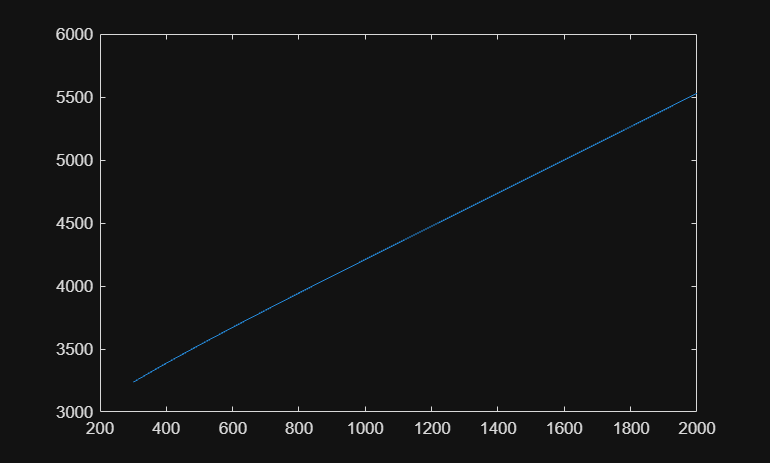

tDay = P - tEclipse;
figure()
plot(alt, tDay)

- Plot the Power Generation Time vs Orbital Altitude. (5 pts)

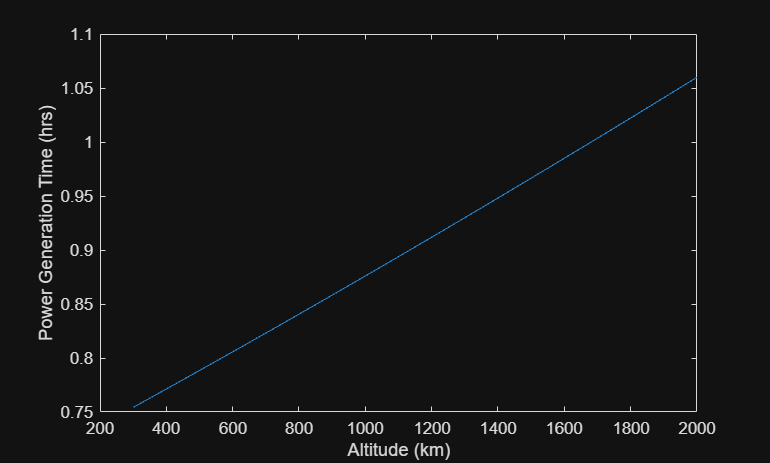

chargeTime = P/2;
dischargeTime = P - chargeTime;
figure()
plot(alt, chargeTime/3600)
xlabel("Altitude (km)")
ylabel("Power Generation Time (hrs)")

- Plot the power required by the spacecraft during daylight vs orbital altitude. (10 pts)

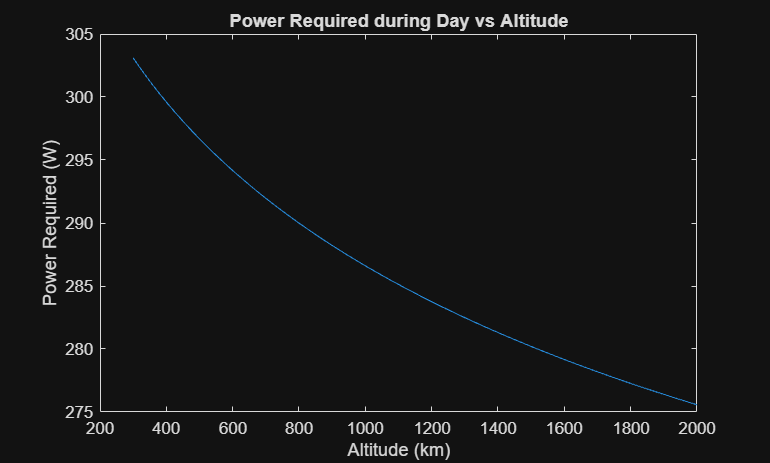

P_payload = 138;
P_structure = 30;
P_thermal = 80;
P_power = 25;
P_data_comms = 40;
P_OBC = 25;

Pconst = P_structure + P_thermal + P_power + P_OBC;
Pnight = (Pconst.*tEclipse + P_data_comms*5*60)./tEclipse;
Pdischarge = (Pconst.*(dischargeTime) + P_data_comms*5*60)./(dischargeTime);

P_charge = Pdischarge.*(dischargeTime)./(chargeTime);

Pday = (Pconst.*tDay + P_payload*2*60 + P_charge.*(dischargeTime))./(tDay);

figure()
plot(alt, Pday)
xlabel("Altitude (km)")
ylabel("Power Required (W)")
title("Power Required during Day vs Altitude")

- Plot the power required by the spacecraft during eclipse vs orbital altitude. (10 pts)

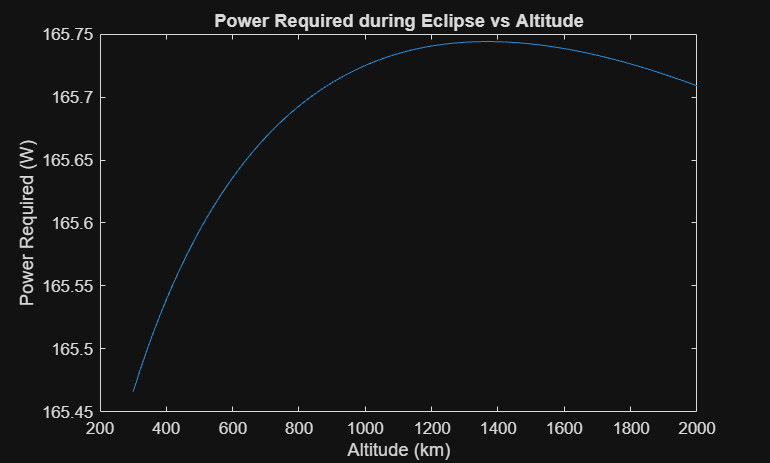

figure()
plot(alt, Pnight)
xlabel("Altitude (km)")
ylabel("Power Required (W)")
title("Power Required during Eclipse vs Altitude")

- Calculate the necessary solar panel surface area to operate the spacecraft and plot it as a function of orbital altitude. (15 pts)

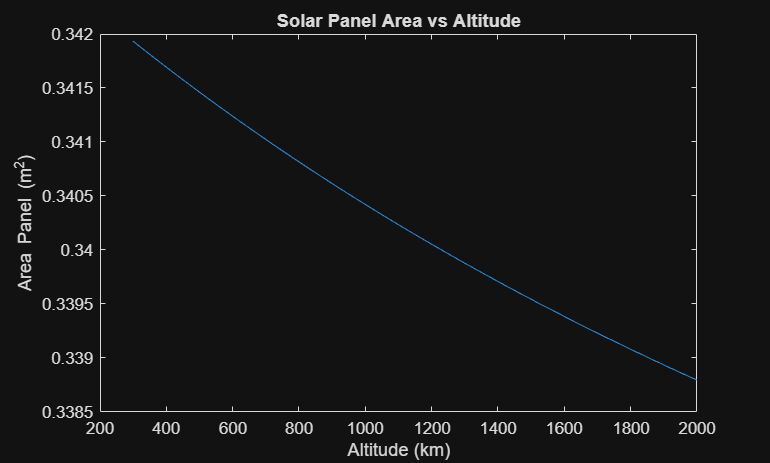

phi = 1367;
eff = 1;
Fp = 1;
theta = 45; % Assumed
Psp = (Pconst.*chargeTime + P_payload*2*60 + P_charge.*chargeTime)./(chargeTime);
Apanel = (Psp)./(phi*eff*Fp*cosd(theta));
figure()
plot(alt, Apanel)
xlabel("Altitude (km)")
ylabel("Area Panel (m^2)")
title("Solar Panel Area vs Altitude")

- Assume that the solar panel efficiency degrades at a rate of 2%/year. Calculate the new solar panel area required to operate the spacecraft with a 10-year lifespan. Plot the area required as a function of orbital altitude (15 pts)

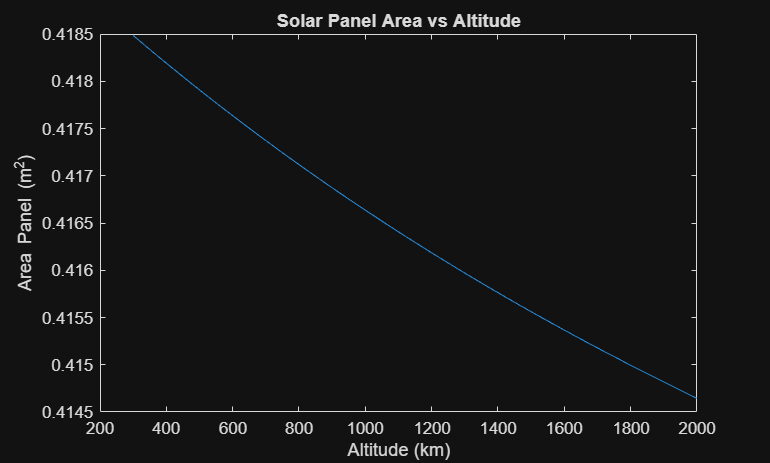

Dyear = 0.02;
LT = 10;
Ld  = (1-Dyear)^LT;
Pnew = Psp/Ld;
Anew = (Pnew)./(phi*eff*Fp*cosd(theta));

figure()
plot(alt, Anew)
xlabel("Altitude (km)")
ylabel("Area Panel (m^2)")
title("Solar Panel Area vs Altitude")

- If the battery on board operates at an efficiency of 80% with an allowed maximum depth of discharge of 50%, plot the variation of battery capacity (in W Hr) vs orbital altitude. Assume the battery is only used during the eclipse. (10 pts)

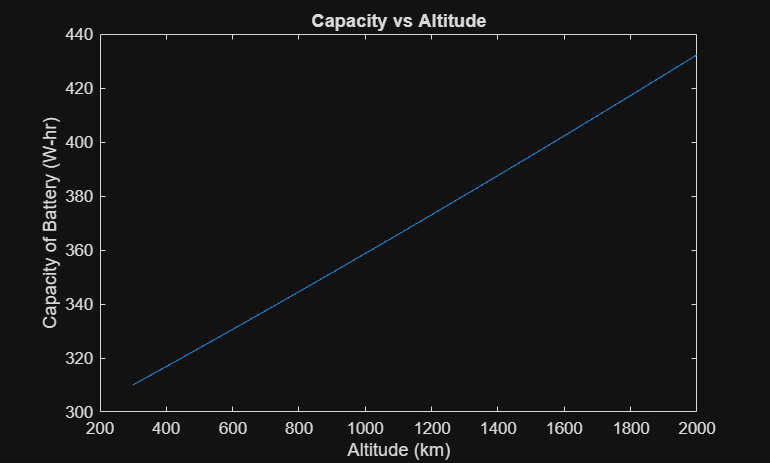

eff = 0.8;
DOD = 0.5;
Capacity = Pdischarge.*dischargeTime/(DOD*eff);
figure()
plot(alt, Capacity/3600)
ylabel("Capacity of Battery (W-hr)")
xlabel("Altitude (km)")
title("Capacity vs Altitude")

- If the mission cost is given by Cmission=Cbaseline+kaltitudeha+ksolarAb . Assume a=1.2,b=1.5,kaltitude=$50,000,ksolar=$5000,Cbaseline=$3,000,000. Plot the mission cost as a function of orbital altitude. (10 pts)

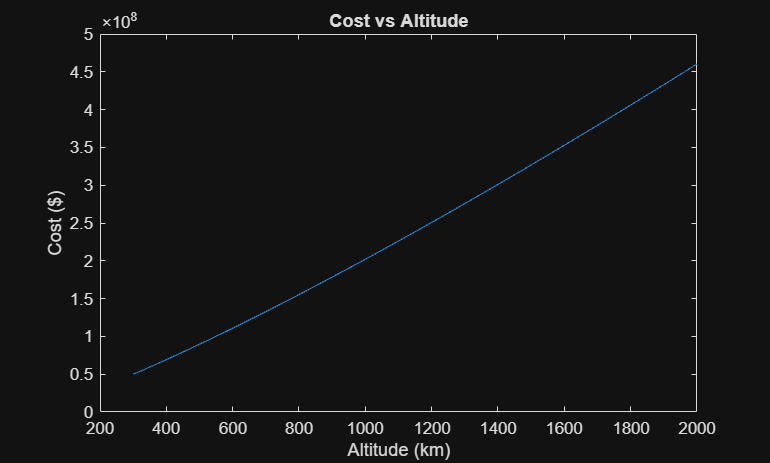

kAlt = 50000;
kSol = 5000;
Cbaseline = 3000000;
a = 1.2;
b = 1.5;
Cmission = Cbaseline + kAlt.*alt.^a + kSol.*Anew.^b;

figure()
plot(alt, Cmission)
title("Cost vs Altitude")
ylabel("Cost ($)")
xlabel("Altitude (km)")

- What is the orbital altitude that minimises the mission cost? Report the associated cost for the mission? (5 pts)

a) The lowest altitude is the lowest cost

disp("Lowest Mission Cost: " + min(Cmission) + " $")

Lowest Mission Cost: 49938373.267 $


disp("Lowest Mission Altitude: " + min(Cmission) + " $")

Lowest Mission Altitude: 49938373.267 $


- Plot the solar power generated by the panels as a function of spacecraft position on the orbit, starting from point A for the optimal altitude. (10 pts)

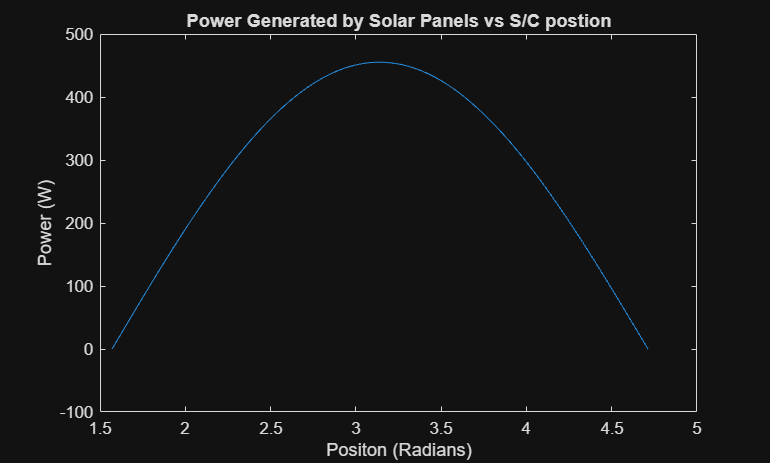

theta2 = linspace(pi/2,3*pi/2, length(alt));
Psp2 = -(Anew).*(phi*eff*Fp*cos(theta2));

figure()
plot(theta2, Psp2)
title("Power Generated by Solar Panels vs S/C postion")
ylabel("Power (W)")
xlabel("Positon (Radians)")